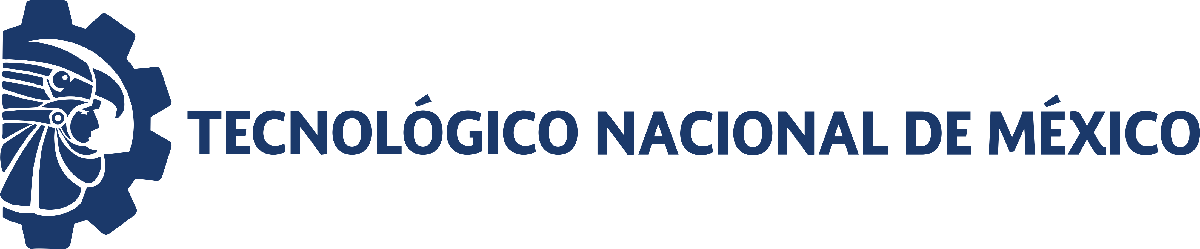                                 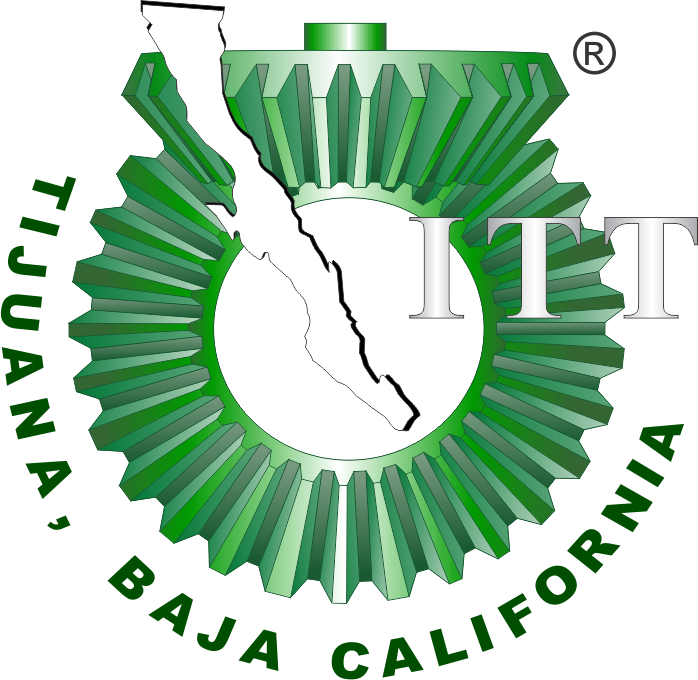

# Práctica 1: Diseño de controlador para un sistema de segundo orden

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

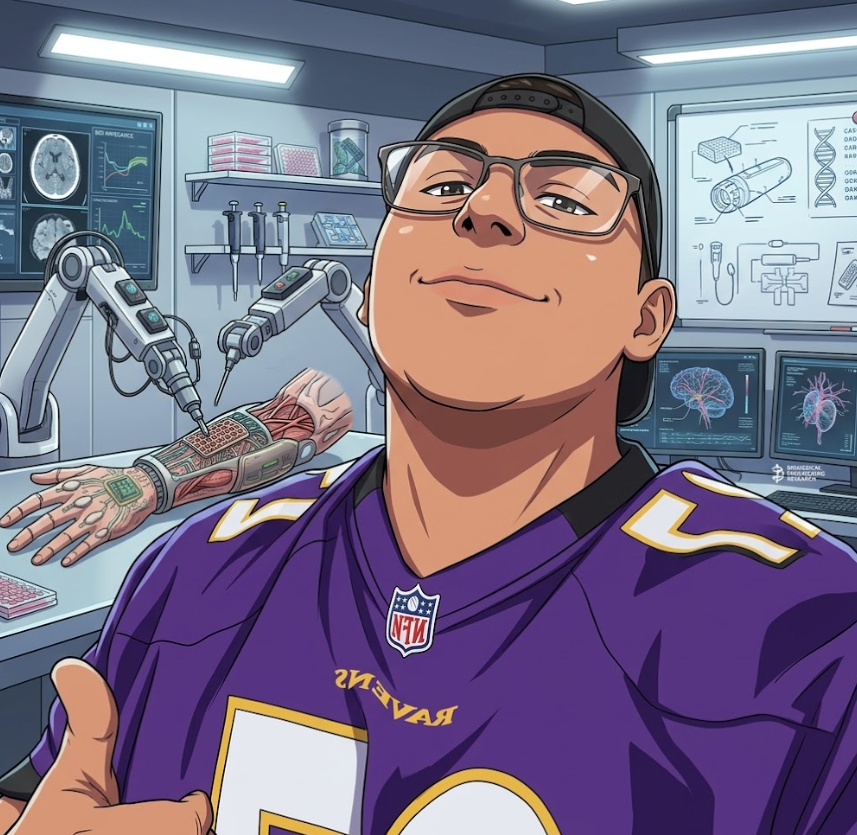

Nombre del alumno: Arredondo Medina Zaid Alexander

Número de control: 23212180

Correo institucional: l23212180**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('SistemaCardiovascular')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

x = sim ('SistemaCardiovascular', parameters);
t_data = (0:0.01:15)';
t= (0:0.001:15)';
Pa = interp1(t_data, x.Pa, t, 'previous');

Pa =     0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420
    0.2420



writematrix(Pa,'signal.xlsx')
%set.param('sistema/Vs(t): CE/Vs', 'VectorFormat', '1-D array');

## Respuesta Normotenso

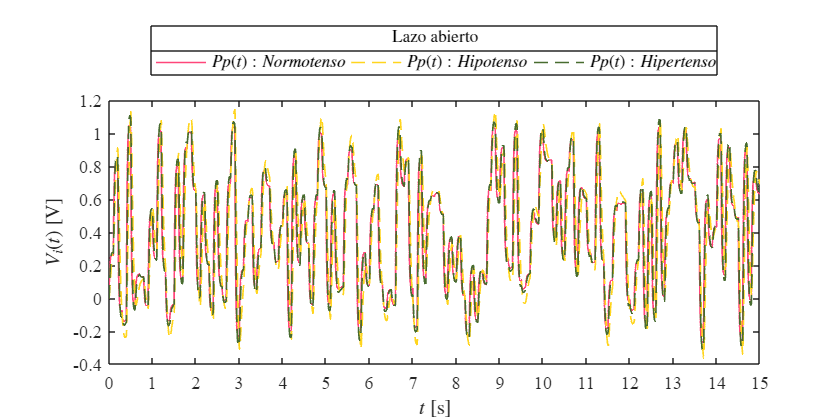

plotSignals(x.t,x.PpN,x.PpL,x.PpH,'Lazo abierto')

## Respuesta Hipotenso

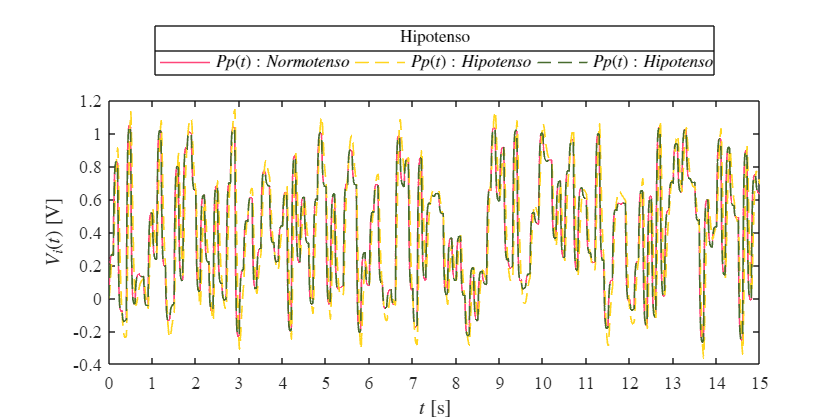

plotSignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Respuesta Hipertenso

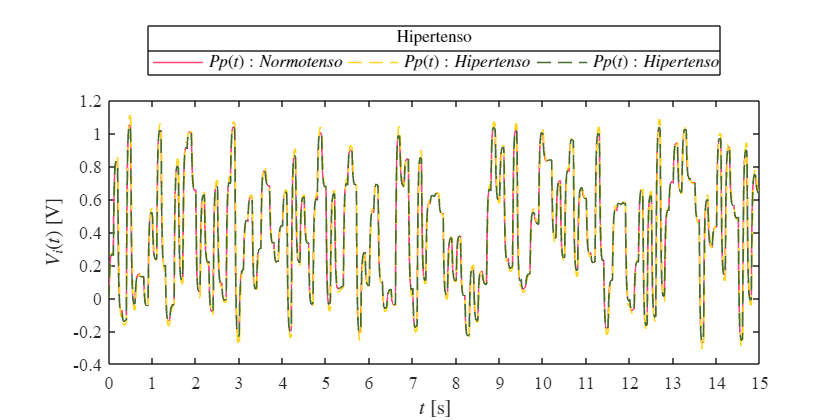

plotSignals(x.t,x.PpN,x.PpH,x.PIDH,'Hipertenso')

Modelo de EDOS

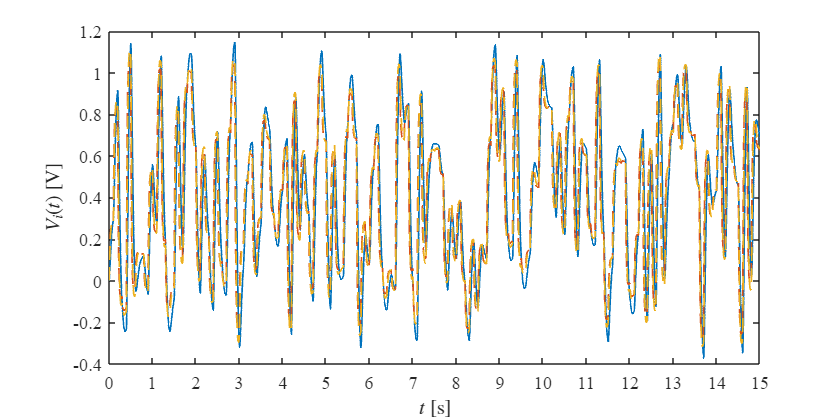

par_hipo  = [0.010,0.001,1.000,3.500]; %[Z,L,R,C]
par_normo = [0.010,0.001,1.000,1.500];
par_hiper = [0.010,0.001,1.000,1.000];
PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotSignals(t,PpL,PpN,PpH,'Individuos (Modelo de EDOs)')

function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4); dt = t(2);
    dt = t(2);
    n = round(t(end)/dt);
    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;
    for i = 1:n
        FL(i+1) = FL(i) + (-(1/L)*Pp(i) + (1/L)*Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C)*FL(i) - (1/(Z*C) + 1/(R*C))*Pp(i) + 1/(Z*C)*Pa(i))*dt;
    end
end

FUNCION: Respuestas de la simulacion

function plotSignals(t,PpN,Pp,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [255, 70, 122]/255;
    clr2 = [255, 213, 30]/255;
    clr3 = [72,108,47]/255;
    if signal == "Lazo abierto"
        order = [clr1;clr2;clr3]; colororder(order)
    elseif signal == "Hipotenso"
        order = [clr1;clr2;clr3]; colororder(order)
    elseif signal == "Hipertenso"
        order = [clr1;clr2;clr3]; colororder(order)
    end
    
    plot(t,PpN,'-',t,Pp,'--',t,PID,'--','LineWidth',1,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    
    if signal == "Lazo abierto"
        L = legend('$Pp(t): Normotenso$','$Pp(t): Hipotenso$','$Pp(t): Hipertenso$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
        title(L,signal)
    elseif signal == "Hipotenso"
        L = legend('$Pp(t): Normotenso$','$Pp(t): Hipotenso$','$Pp(t): Hipotenso$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
        title(L,signal)
    elseif signal == "Hipertenso"
        L = legend('$Pp(t): Normotenso$','$Pp(t): Hipertenso$','$Pp(t): Hipertenso$');
        set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
        title(L,signal)
    end
    
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
    
    xlim([0 15]); xticks(0:1:15)
    ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
    
    exportgraphics(gcf,[signal,'_matlab.pdf'],'contenttype','vector')
end